# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** : 정성은        **

**학번**** : 201716308**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : https://github.com/SeongEunJeong/HW2/blob/master/HW1_201716308_%EC%A0%95%EC%84%B1%EC%9D%80.mlx**

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 

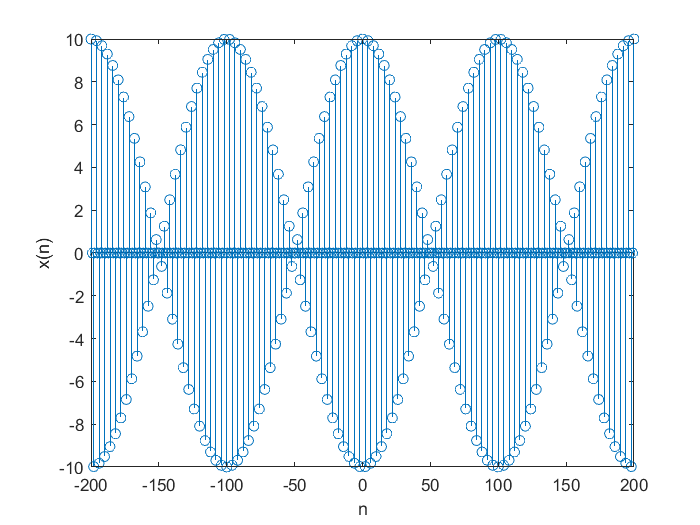

n=[-200:200]; 
x5=5*(cos(0.49*pi*n)+cos(0.51*pi*n));

stem(n,x5);
xlabel('n'); ylabel('x(n)');

2) 

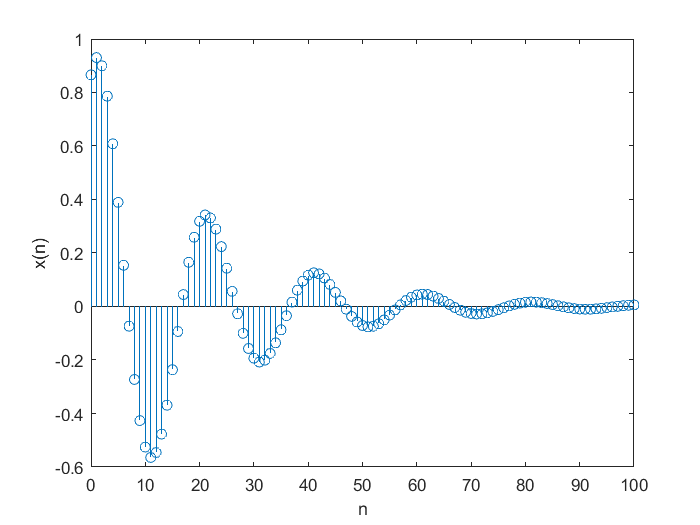

n=[0:100];
x7=exp(-0.05*n).*sin(0.1*pi*n+pi/3);

stem(n,x7);
xlabel('n'); ylabel('x(n)');

2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.

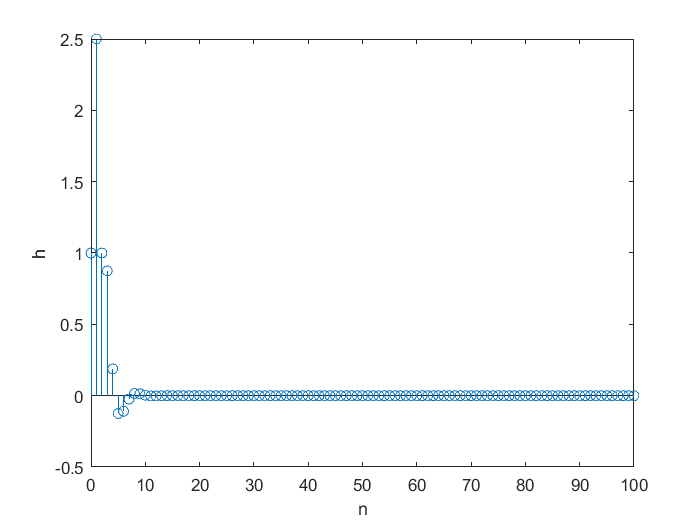

n=[0:100];
b=[1, 2, 0, 1]; a=[1, -0.5, 0.25];
h=impz(b,a,n);

stem(n,h);  
xlabel('n'); ylabel('h');

2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)

sum(abs(h))

ans = 5.8571

%ans=5.8571 나왔으므로 유한하다. 그러므로 안정하다.

3) 만약 이 시스템의 입력이  이면, filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

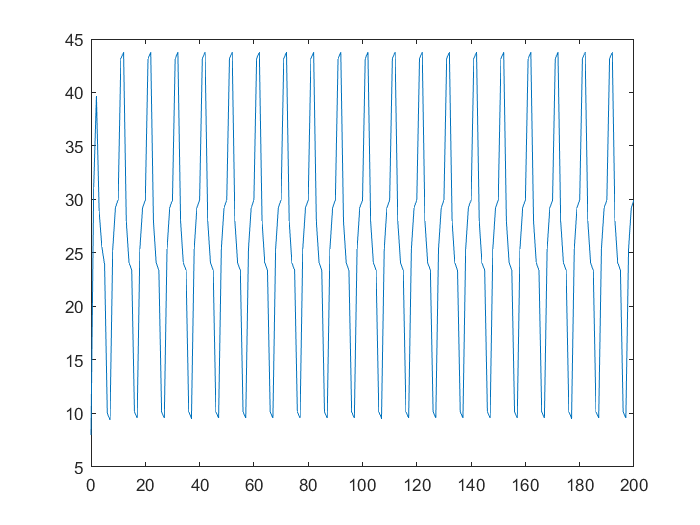

n=[0:200];
b=[1 2 0 1]; a=[1 -0.5 0.25]; 
x=5*ones(size(n))+3*cos(0.2*pi*n)+4*sin(0.6*pi*n);
s=filter(b,a,x);
plot(n,s);

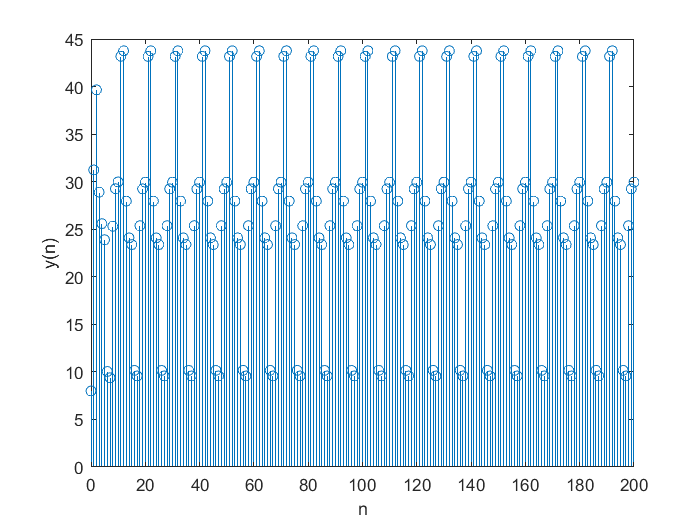

stem(n,s);  
xlabel('n'); ylabel('y(n)');

3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 

n = [0:50]; x=(0.8).^n; h=(-0.9).^n;

y1 = ((0.8).^(n+1) - (-0.9).^(n+1))/(0.8+0.9);
subplot(1,3,1); 
stem(n,y1);


2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. 

n=[0:25];

x= (0.8).^(n); h=(-0.9).^(n);
y2=conv(h,x);

subplot(1,3,2); 
stem([0:50],y2);


3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 

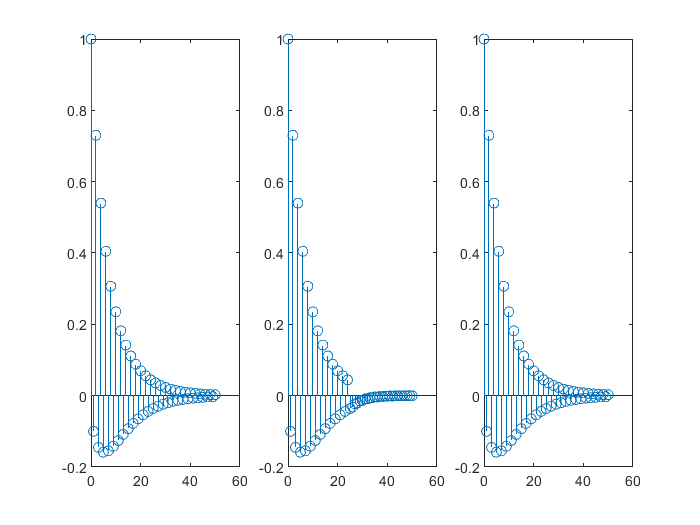

n=[0:50];

x= (0.8).^(n); h=(-0.9).^(n);
%filter를 쓰기 위해 차분방정식을 먼저 구한다.
%그러기 위해 임펄스응답 h(n)에 의해 주어진 LTI시스템을 차분방정식으로 기술
%y(n)+0.9*y(n-1)=x(n)
b=[1];  a=[1 0.9];
y3=filter(b,a,x);

subplot(1,3,3); 
stem(n,y3);

4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$

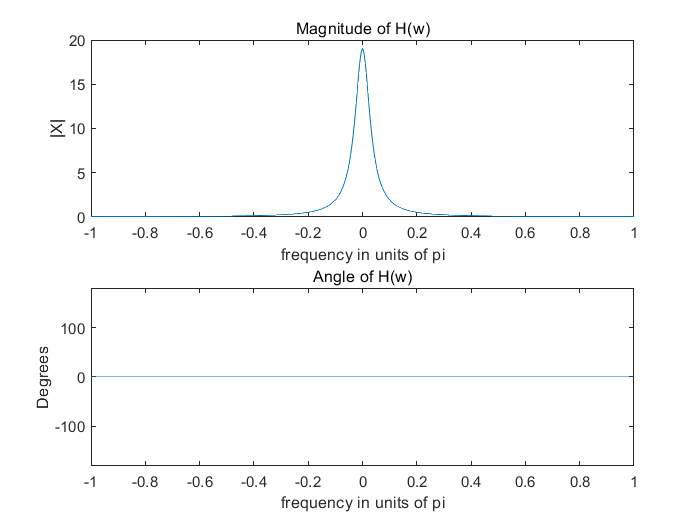

 %n=-5:5;
 %x=(0.9).^n
 %k=0:200;
 %w=(pi/100)*k;
 %X=x*(exp(-j*pi/100)).^(n'*k);
%magX=abs(X); angX=angle(X);
 %subplot(2,1,1); plot(w/pi,magX);
%%%%%%%%%%%%%%%%
 % h(n) = (0.9)^(abs(n)); H(w) = 0.19/(1.81-1.8*cos(w);
 

 w=[-300:300]*pi/300;
 H=0.19*ones(size(w))./(1.81-1.8*cos(w));
 magH=abs(H); angH=angle(H)*180/pi;
 
 subplot(2,1,1);plot(w/pi,magH);
 title('Magnitude of H(w)');
 xlabel('frequency in units of pi');
 ylabel('|X|');
 
 
 subplot(2,1,2); plot(w/pi,angH);axis([-1 1 -180 180]);
 title('Angle of H(w)');
 xlabel('frequency in units of pi');
 ylabel('Degrees');

2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$

%n=0:10;
%h=((0.5).^(n)+(0.4).^(n))
%k=-100:100; 
%w=(pi/100)*k;
%X=x*(exp(-j*pi/100)).^(n'*k);
%magX=abs(X); angX=angle(X);
 %subplot(2,1,1); plot(w/pi,magX);
 %xlabel('frequency in units of pi');
 %ylabel('|X|');
 %title('Magnitude Part'); 
 %subplot(2,1,2); plot(w/pi,angX/pi);
 %xlabel('frequency in units of pi');
% ylabel('radians/pi');
% title('Angle Part'); 
%%%%%%%%%%%%%%%%%%%%

%H(w)=(2-0.9*exp(-j*w))./(1-0.9*exp(-j*w)+0.2*exp(-j*2*w))
clc;
w=[-300:300]*pi/300;
H=(2-0.9*exp(-j*w))./(1-0.9*exp(-j*w)+0.2*exp(-j*2*w))

H =    1.3810 + 0.0000i   1.3810 + 0.0045i   1.3810 + 0.0089i   1.3810 + 0.0134i   1.3811 + 0.0179i   1.3812 + 0.0223i   1.3813 + 0.0268i   1.3814 + 0.0313i   1.3815 + 0.0357i   1.3817 + 0.0402i   1.3818 + 0.0447i   1.3820 + 0.0491i   1.3822 + 0.0536i   1.3825 + 0.0581i   1.3827 + 0.0626i   1.3830 + 0.0670i   1.3832 + 0.0715i   1.3835 + 0.0760i   1.3838 + 0.0805i   1.3842 + 0.0850i   1.3845 + 0.0895i   1.3849 + 0.0940i   1.3853 + 0.0985i   1.3857 + 0.1030i   1.3861 + 0.1075i   1.3865 + 0.1120i   1.3870 + 0.1165i   1.3875 + 0.1210i   1.3880 + 0.1255i   1.3885 + 0.1300i   1.3890 + 0.1345i   1.3896 + 0.1391i   1.3902 + 0.1436i   1.3907 + 0.1481i   1.3914 + 0.1527i   1.3920 + 0.1572i   1.3926 + 0.1618i   1.3933 + 0.1663i   1.3940 + 0.1709i   1.3947 + 0.1755i   1.3955 + 0.1800i   1.3962 + 0.1846i   1.3970 + 0.1892i   1.3978 + 0.1938i   1.3986 + 0.1984i   1.3994 + 0.2030i   1.4003 + 0.2076i   1.4011 + 0.2122i   1.4020 + 0.2168i   1.4030 + 0.2215i


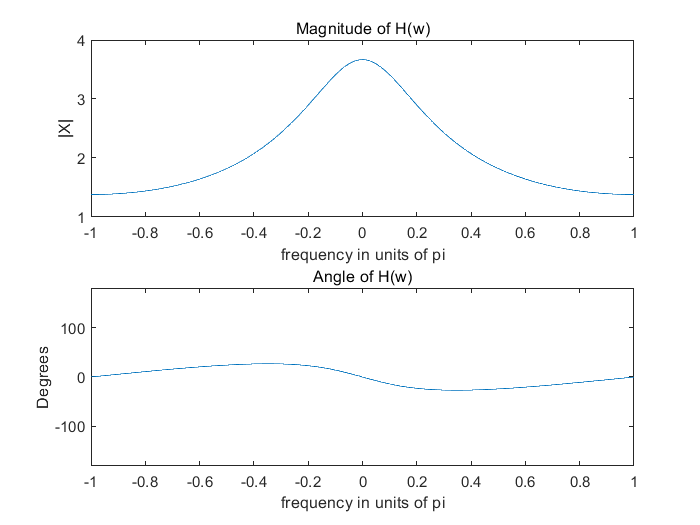

magH = abs(H); angH = angle(H)*180/pi; 

 subplot(2,1,1);plot(w/pi,magH);
 title('Magnitude of H(w)');
 xlabel('frequency in units of pi');
 ylabel('|X|');
 
 
 subplot(2,1,2); plot(w/pi,angH); axis([-1 1 -180 180]);

 title('Angle of H(w)');
 xlabel('frequency in units of pi');
 ylabel('Degrees');

5. (P3.17) 

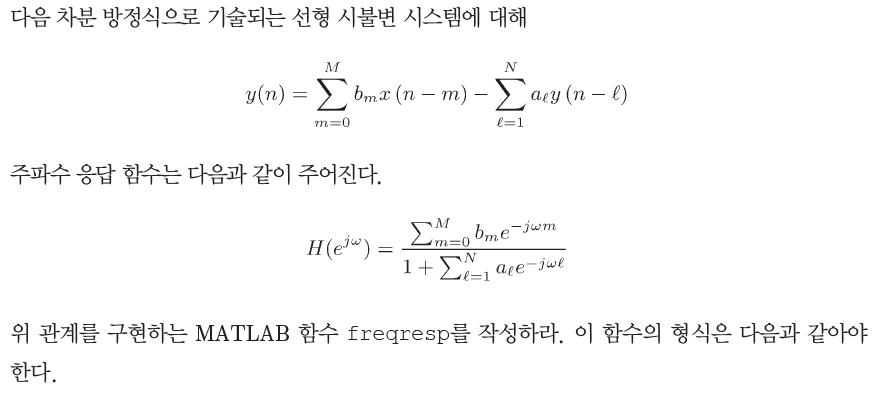

function [H] = freqresp(b,a,w)

% Frequency response function from difference equation
% [H] = freqresp(b,a,w)
% H = frequency response array evaluated at w frequencies
% b = numerator coefficient array
% a = denominator coeeficient array (a(1) = 1)
% w = frequency location array

m=0:length(b)-1;
l=0:length(a)-1;
num=b*exp(-j*m'*w);
den=a*exp(-j*l'*w);
[H]=num./den;

end 

6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$

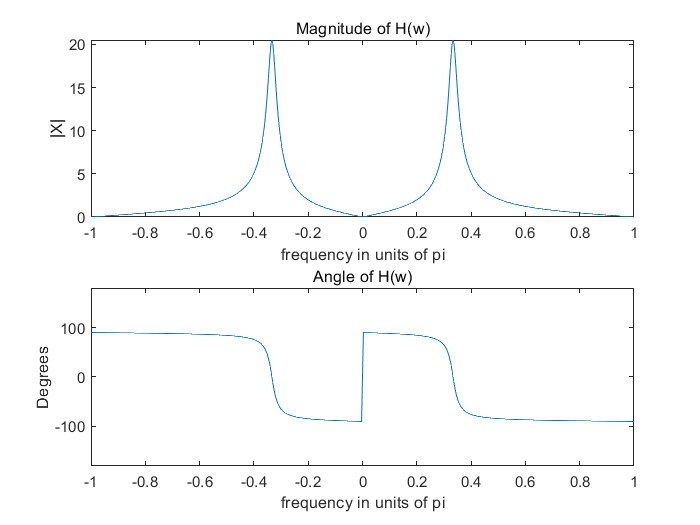

%H=(1-exp(-2*j*w))./(1-0.984*exp(-j*w)+0.9025*exp(-2*j*w));
w=[-300:300]*pi/300;
b=[1, 0, -1]; a=[1, -0.95, 0.9025];
m=0:length(b)-1;
l=0:length(a)-1;
w=[-300:300]*pi/300;
num=b*exp(-j*m'*w);
den=a*exp(-j*l'*w);
H=num./den;
magH = abs(H); angH = angle(H)*180/pi; 

subplot(2,1,1);plot(w/pi,magH);
 title('Magnitude of H(w)');
 xlabel('frequency in units of pi');
 ylabel('|X|');
subplot(2,1,2); plot(w/pi,angH); axis([-1 1 -180 180]);
 title('Angle of H(w)');
 xlabel('frequency in units of pi');
 ylabel('Degrees');

2) $y\left(n\right)=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^n y\left(n-l\right)$

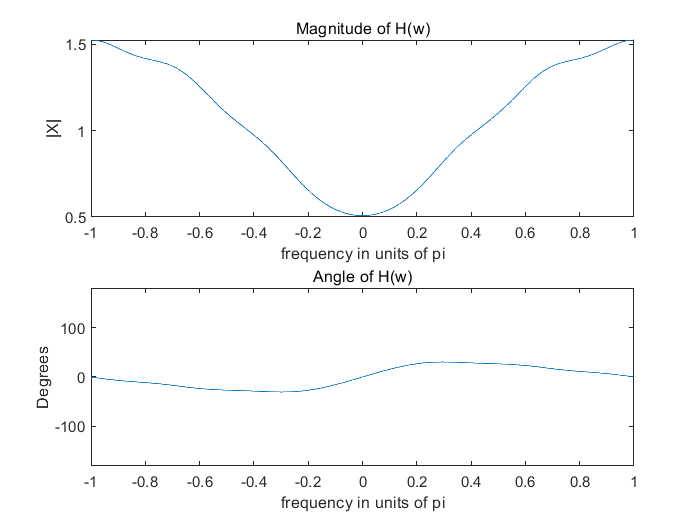

%H=ones(size(w))./(1+(0.5)^(1)*exp(-j*w)+(0.5)^(2)*exp(-2*j*w)+(0.5)^(3)*exp(-3*j*w)+(0.5)^(4)*exp(-4*j*w)+(0.5)^(5)*exp(-5*j*w))
w=[-300:300]*pi/300;
b=[1]; a=[1, 0.5, 0.5^2, 0.5^3, 0.5^4, 0.5^5];
m=0:length(b)-1;
l=0:length(a)-1;
w=[-300:300]*pi/300;
num=b*exp(-j*m'*w);
den=a*exp(-j*l'*w);
H=num./den;
magH = abs(H); angH = angle(H)*180/pi; 

subplot(2,1,1);plot(w/pi,magH);
 title('Magnitude of H(w)');
 xlabel('frequency in units of pi');
 ylabel('|X|');
subplot(2,1,2); plot(w/pi,angH); axis([-1 1 -180 180]);
 title('Angle of H(w)');
 xlabel('frequency in units of pi');
 ylabel('Degrees');